% Script per leggere file EDF, preparare d e hdr e usare LSM_spindle_probabilities e LSM_spindle_detections

if exist('input_param', 'var')
    % Esegui operazioni con input_param
    file_path = input_param;  % Operazione di esempio
else
    error('input_param non è definito');
end


sections_to_analyze = [];
if ~isempty(csv_file) && isfile(csv_file)
    % Leggi il CSV
    csv_data = readtable(csv_file);
    %disp('Nomi delle colonne effettivi nel CSV:');
    %disp(csv_data.Properties.VariableNames);

    if all(ismember({'start', 'xEnd'}, csv_data.Properties.VariableNames))
        sections_to_analyze = csv_data;
    else
        error('Il file CSV deve contenere le colonne "start" e "end".');
    end
end


% 1. Definisci il percorso del file EDF C:\Users\matti\Documents\MATLAB
%file_path = '.\Edf\1.edf';  % Cambia con il percorso corretto
percorso = '.\Risultati';


if ~exist(percorso, 'dir')
   mkdir(percorso);
end

% Canali da escludere
channels_to_exclude = {'EEGA1', 'EEGA2', 'Oculo', 'MK','ECG','EMG1','EMG2'};

% 2. Leggi il file EDF
data_table = edfread(file_path);

% Nome del file senza estensione (per creare una cartella di output)
[~, filename, ~] = fileparts(file_path);
    
% Crea una cartella specifica per questo file EDF all'interno di Risultati
output_folder = fullfile(percorso, filename);
if ~exist(output_folder, 'dir')
   mkdir(output_folder);
end

%disp(data_table);
hdr = struct();  % Crea una nuova struttura per hdr
hdr.info = struct();  % Aggiungi un campo info nella struttura hdr

% Aggiungi la frequenza di campionamento all'intestazione (hdr.info.sfreq)
hdr.info.sfreq = 128;

% Estrai le informazioni dell'intestazione (hdr)
hdr.info.ch_names = data_table.Properties.VariableNames;  % I nomi delle colonne rappresentano i canali

parameter_file = 'Original_Spindle_Detector.mat';

% 4. Estrai i dati del segnale (d)
data_table = removevars(data_table, channels_to_exclude);

dati = table2array(data_table);  % Converti la tabella in una matrice numerica

dati = dati';

data_matrix  = cell2mat(dati'); % Concatenazione verticale

tot_spindle = 0;

data_matrix_full = data_matrix';

%limitazioni per questioni di testin
%hdr.info.ch_names = hdr.info.ch_names(1:4);  % Prendi solo i primi due nomi

%data_matrix=data_matrix(1:4, :);

%%%%%%fine limitazioni


if ~isempty(sections_to_analyze)
    fprintf('Analizzando le sezioni definite nel file CSV...\n');
    selected_data = [];
    for i = 1:height(sections_to_analyze)
        % Ottieni gli indici di inizio e fine per la sezione corrente
        start_time = sections_to_analyze.start(i) * 60;
        end_time = sections_to_analyze.xEnd(i) * 60;

        % Converti tempo in secondi in indici di campione
        start_sample = max(1, round(start_time * hdr.info.sfreq)); % Arrotonda agli indici
        end_sample = min(size(data_matrix_full, 2), round(end_time * hdr.info.sfreq)); % Arrotonda agli indici

        % Estrai i dati della sezione
        selected_data = [selected_data, data_matrix_full(:, start_sample:end_sample)];
    end

    data_matrix = selected_data;  % Sovrascrivi data_matrix con i dati selezionati
else
    fprintf('Nessuna sezione specificata nel file CSV. Usando tutto il segnale.\n');
    data_matrix = data_matrix_full;  % Usa tutti i dati
end

%rimozione dei canali non desiderati
exclude_idx = ismember(hdr.info.ch_names, channels_to_exclude);
hdr.info.ch_names(exclude_idx) = [];

channel_names = hdr.info.ch_names;

disp("inzio lsm_prob")

inzio lsm_prob


% 6. Esegui il rilevamento degli stati latenti (LS)

% Step 6.1: Calcolo delle probabilità di rilevamento del fuso
spindle_prob = LSM_spindle_probabilities(data_matrix, hdr, parameter_file);

Detecting spindles with spectral features: broadband  
Loading pre-computed bandpass filter. 

C:\Users\matti\Documents\MATLAB

... using likelihood file Original_Spindle_Detector.mat
... EEGFp1(1 of 2) 


... using likelihood file Original_Spindle_Detector.mat
... EEGFp2(2 of 2) 



disp("finito lsm_prob")

finito lsm_prob


disp("inzio lsm_detections")

inzio lsm_detections



% Step 6.2: Rilevamento del fuso
spindle_det = LSM_spindle_detections(spindle_prob);

disp("finito lsm_detections")

finito lsm_detections



% 7. Visualizza i risultati
%disp('Probabilità di fuso (spindle_prob):');

Probabilità di fuso (spindle_prob):


%disp(spindle_prob)

  2×1 struct array with fields:

    label
    prob
    t
    Fs
    params




%disp('Rilevamento del fuso (spindle_det):');

Rilevamento del fuso (spindle_det):


%disp(spindle_det);

  1×2 struct array with fields:

    startSample
    endSample
    label
    Fs



Durate degli spindle per il canale EEGFp1:


    1.9297    0.9141    0.7109    0.9141    4.3672    1.6250    1.0156    2.5391    1.4219    1.8281    0.6094    1.7266    3.4531    1.0156    2.0312    0.8125    0.6094    0.7109    0.7109    1.6250    1.0156    0.8125    3.5547    1.3203    0.6094    0.9141    0.8125    2.4375    0.6094    1.4219    2.1328    3.1484    2.2344    1.1172    0.7109    1.3203    1.3203    0.9141    0.6094    0.6094    0.8125    0.7109    1.2188    0.6094    5.5859    3.0469    0.7109    1.5234    1.1172    6.6016    2.8438    1.3203    1.6250    0.6094    0.6094    1.3203    1.6250    1.1172    0.7109    0.8125    1.0156    3.0469    0.7109    0.8125    1.4219    1.1172    0.6094    0.7109    1.9297    0.6094    0.9141    1.4219    0.6094    0.6094    0.8125    0.8125    0.7109    1.0156    0.6094    2.6406    0.7109    2.0312    0.6094    1.7266    0.7109    0.8125    0.8125    1.7266    0.8125    2.3359    1.3203    1.1172    1.3203    2.0312    0.8125    0.6094    2.1328    0.6094    0.6094    0.8125

Il minimo ISI è: 0.91406     0.91406     0.91406     0.91406     0.91406     0.91406     0.91406      1.0156      1.0156      1.0156      1.0156      1.0156      1.0156      1.0156      1.0156      1.1172      1.1172      1.1172      1.1172      1.1172      1.1172      1.1172      1.1172      1.1172      1.2188      1.2188      1.2188      1.2188      1.2188      1.2188      1.2188      1.2188      1.2188      1.2188      1.3203      1.3203      1.3203      1.3203      1.3203      1.3203      1.3203 secondi


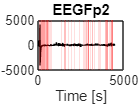

Durate degli spindle per il canale EEGFp2:


    2.1328    0.6094    4.5703    1.3203    2.0312    2.8438    0.7109    0.7109    0.6094    4.4688    0.7109    1.6250    0.7109    0.8125    0.6094    0.6094    1.1172    1.1172    2.8438    1.4219    1.1172    1.0156    0.7109    1.9297    0.9141    1.4219    1.2188    0.8125    0.6094    0.9141    1.3203    0.7109    1.4219    1.2188    1.2188    0.6094    1.2188    0.7109    0.7109    1.4219    5.3828    3.6562    0.8125    1.5234    1.0156    0.6094    1.2188    2.9453    2.1328    0.9141    0.7109    1.8281    0.9141    0.6094    1.4219    1.2188    1.4219    3.5547    1.4219    1.1172    3.7578    1.6250    2.5391    0.7109    0.8125    1.7266    0.6094    1.0156    2.8438    0.6094    0.8125    0.8125    0.6094    0.6094    0.8125    0.7109    1.4219    5.5859    0.8125    2.1328    1.8281    3.7578    0.7109    0.8125    5.0781    3.1484    1.7266    0.6094    1.4219    0.6094    1.5234    0.8125    3.1484    1.0156    2.6406    0.9141    2.3359    2.0312    0.6094    1.2188

Il minimo ISI è: 0.91406     0.91406     0.91406     0.91406     0.91406     0.91406     0.91406     0.91406      1.0156      1.0156      1.0156      1.0156      1.0156      1.0156      1.0156      1.1172      1.1172      1.1172      1.1172      1.1172      1.1172      1.1172      1.1172      1.1172      1.2188      1.2188      1.2188      1.2188      1.2188      1.2188      1.2188      1.2188      1.2188      1.2188      1.2188      1.2188      1.2188      1.2188      1.2188      1.3203      1.3203      1.3203 secondi



isi_min_struct = struct();
durate_spindle_per_canale = struct();

% Cicla su tutti i canali
for i = 1:length(channel_names)
    
    % Estrai il nome del canale corrente
    channel = channel_names{i};
    
    % Crea il nome file per il canale corrente
    file_jpg = fullfile(output_folder, ['spindle_detection_' channel '.jpg']);
    
    % Esegui la visualizzazione per il canale corrente
    LSM_spindle_visualizer(data_matrix, hdr, spindle_det, channel);
    
    % Salva l'immagine come JPG
    saveas(gcf, file_jpg);


    %calcolo durata spindle
    spindle_labels = {spindle_det.label};  % Estrai tutti i label
  
    spindle_indices = strcmp(spindle_labels, channel);

    startSamples = [spindle_det(spindle_indices).startSample];
    endSamples = [spindle_det(spindle_indices).endSample];

    num_spindles = length(startSamples);

    durate_spindle = zeros(1, num_spindles);

    for j = 1:num_spindles
        durata = (endSamples(j) - startSamples(j)) / hdr.info.sfreq;  % Durata in secondi / hdr.info.sfreq
        durate_spindle(j) = durata;
    end

    durate_spindle_per_canale(i).canale = channel;
    durate_spindle_per_canale(i).durate = durate_spindle;

    disp(['Durate degli spindle per il canale ' channel ':']);
    disp(durate_spindle);


    %calcolo isi min

    if num_spindles > 1
        % Prealloca un array per gli ISI
        isi = zeros(1, num_spindles - 1);
        
        % Calcola l'ISI tra ogni spindle successivo
        for j = 1:(num_spindles - 1)
            % Intervallo tra la fine dello spindle j e l'inizio dello spindle j+1
            isi(j) = (startSamples(j+1) - endSamples(j)) / hdr.info.sfreq;  % ISI in secondi
        end
       
        % Ordina gli ISI
        isi_sorted = sort(isi);

        % Calcola il numero di ISI da considerare (10%)
        num_to_consider = max(1, floor(0.1 * length(isi_sorted)));

        % Prendi i 10% più piccoli ISI
        isi_min = isi_sorted(1:num_to_consider);

        %assegna il nome del canale e gli isi all'iterno della struttura
        isi_min_struct(i).canale = channel;
        isi_min_struct(i).isi_min = isi_min;
        
        % Visualizza l'ISI minimo
        disp(['Il minimo ISI è: ' num2str(isi_min) ' secondi']);
    else
        disp('Non ci sono abbastanza spindle per calcolare isi min.');
    end

    % calcolo del tasso

    num_samples = size(data_matrix, 2); %data_matrix
    durata_segnale = num_samples / hdr.info.sfreq;  % Durata del segnale in secondi
    durata_segnale = durata_segnale / 60; %durata segnale in minuti
    

    tot_spindle = tot_spindle + num_spindles;
end    


%tasso totale 
num_samples = size(data_matrix, 2); %data_matrix
durata_segnale = num_samples / hdr.info.sfreq;  % Durata del segnale in secondi
durata_segnale = durata_segnale / 60; %durata segnale in minuti

tasso_totale = (tot_spindle / durata_segnale );

disp("tasso totale")

tasso totale


disp(tasso_totale)

   11.2660




emisfero_sinistro = {'EEGFp1', 'EEGF3','EEGC3', 'EEGP3'};
emisfero_destro = {'EEGFp2', 'EEGF4', 'EEGC4', 'EEGP4'};
ritardi_interemisferici_struct = struct();

% Loop su tutte le coppie di canali
for i = 1:length(emisfero_sinistro)
    canale_sx = emisfero_sinistro{i};
    canale_dx = emisfero_destro{i};
    
    % Trova i tempi di inizio per il canale sinistro
    tempi_inizio_sx = [];
    tempi_fine_sx = [];
    tempi_inizio_dx = [];
    tempi_fine_dx = [];
    
    for j = 1:length(spindle_det)
        label = spindle_det(j).label;
        startSample = spindle_det(j).startSample;
        endSample = spindle_det(j).endSample;
        
        if strcmp(label, canale_sx)
            tempi_inizio_sx = startSample;  % Tempi di inizio per il canale sinistro
            tempi_fine_sx = endSample;      % Tempi di fine per il canale sinistro
        elseif strcmp(label, canale_dx)
            tempi_inizio_dx = startSample;  % Tempi di inizio per il canale destro
            tempi_fine_dx = endSample;      % Tempi di fine per il canale destro
        end
    end
    
    % calcolo il ritardo
    ritardi_sincroni_sx_dx = [];
    ritardi_sincroni_dx_sx = [];
    
    % Per ogni spindle sinistro, cerca il prossimo spindle destro
    for k = 1:length(tempi_inizio_sx)
        t_sx_start = tempi_inizio_sx(k);
        t_sx_end = tempi_fine_sx(k);
        
        % Trova il primo spindle nel canale destro che ha inizio dentro l'intervallo del sinistro
        spindle_dx_in_range = find(tempi_inizio_dx >= t_sx_start & tempi_inizio_dx <= t_sx_end);
        
        if ~isempty(spindle_dx_in_range)

            % Prende il primo spindle destro che rientra nell'intervallo dello spindle sinistro
            ritardo = (tempi_inizio_dx(spindle_dx_in_range(1)) - t_sx_start) / hdr.info.sfreq;
            ritardi_sincroni_sx_dx = [ritardi_sincroni_sx_dx, ritardo];
            %disp(ritardo)
        end
    end

    % Calcolo ritardi interemisferici (destra -> sinistra)
    for k = 1:length(tempi_inizio_dx)
        t_dx_start = tempi_inizio_dx(k);
        t_dx_end = tempi_fine_dx(k);
        
        % Trova il primo spindle nel canale sinistro che ha inizio dentro l'intervallo del destro
        spindle_sx_in_range = find(tempi_inizio_sx >= t_dx_start & tempi_inizio_sx <= t_dx_end);
        
        if ~isempty(spindle_sx_in_range)
            % Prende il primo spindle sinistro che rientra nell'intervallo dello spindle destro
            ritardo = (tempi_inizio_sx(spindle_sx_in_range(1)) - t_dx_start) / hdr.info.sfreq;
            ritardi_sincroni_dx_sx = [ritardi_sincroni_dx_sx, ritardo];
            %disp(ritardo)
        end
    end
    
    ritardi_interemisferici_struct(i).canale_sx = canale_sx;
    ritardi_interemisferici_struct(i).canale_dx = canale_dx;
    ritardi_interemisferici_struct(i).ritardi_sx_dx = ritardi_sincroni_sx_dx;  % Ritardi da sinistra a destra
    ritardi_interemisferici_struct(i).ritardi_dx_sx = ritardi_sincroni_dx_sx;  % Ritardi da destra a sinistra

end


Ritardi interemisferici:


  1×4 struct array with fields:

    canale_sx
    canale_dx
    ritardi_sx_dx
    ritardi_dx_sx



%preparazione salvtaggio su file csv
dati_ritardo_csv = {'Canale_SX', 'Canale_DX', 'Direzione', 'Ritardo(s)'};


% Loop su tutte le coppie di canali e aggiungi i dati al file
for i = 1:length(ritardi_interemisferici_struct)
    canale_sx = ritardi_interemisferici_struct(i).canale_sx;
    canale_dx = ritardi_interemisferici_struct(i).canale_dx;
    ritardi_c_sx_dx = ritardi_interemisferici_struct(i).ritardi_sx_dx;
    ritardi_c_dx_sx = ritardi_interemisferici_struct(i).ritardi_dx_sx;
    %ritardi_secondi = ritardi_interemisferici_struct(i).ritardi_sec;
    
    % Converti i vettori di ritardi in stringhe per salvare nel CSV
    %ritardi_c_sx_dx_str = sprintf('%.2f ', ritardi_c_sx_dx);  % Stringa di ritardi in campioni
    %ritardi_c_dx_sx_str = sprintf('%.2f ', ritardi_c_dx_sx);
    %ritardi_secondi_str = sprintf('%.2f ', ritardi_secondi);    % Stringa di ritardi in secondi
    
    % Aggiungi una riga alla cella contenente i dati
    %dati_ritardo_csv(end+1, :) = {canale_sx, canale_dx, ritardi_c_sx_dx_str,ritardi_c_dx_sx_str};
       % Aggiungi i dati per ritardi_sx_dx
    for j = 1:length(ritardi_c_sx_dx)
        dati_ritardo_csv(end+1, :) = {canale_sx, canale_dx, 'sx_dx', ritardi_c_sx_dx(j)};
    end
    
    % Aggiungi i dati per ritardi_dx_sx
    for j = 1:length(ritardi_c_dx_sx)
        dati_ritardo_csv(end+1, :) = {canale_sx, canale_dx, 'dx_sx', ritardi_c_dx_sx(j)};
    end
end


dati_tasso_csv = {'Tasso'};
tasso_totale_str = sprintf('%.2f ', tasso_totale);
dati_tasso_csv(end+1, :) = {tasso_totale_str};

dati_tasso_csv = 2×1 cell array
    {'Tasso' }
    {'11.27 '}




dati_isi_csv = {'Canale','isi_min(s)'};

for i = 1:length(isi_min_struct)
    canale = isi_min_struct(i).canale;
    %durate = durate_spindle_per_canale(i).durate;
    isi_min = isi_min_struct(i).isi_min;

    %durate_str = sprintf('%.4f ', durate);

    %isi_min_str = sprintf('%.4f ', isi_min);


     for j = 1:length(isi_min)
        dati_isi_csv(end+1, :) = {canale, isi_min(j)};
     end

    %dati_isi_csv(end+1, :) = {canale, isi_min_str, durate_str};
end


dati_durata_csv = {'Canale','durata(s)'};

for i = 1:length(durate_spindle_per_canale)
    canale = isi_min_struct(i).canale;
    durate = durate_spindle_per_canale(i).durate;
    %isi_min = isi_min_struct(i).isi_min;

    %durate_str = sprintf('%.4f ', durate);

    %isi_min_str = sprintf('%.4f ', isi_min);


     for j = 1:length(durate)
        dati_durata_csv(end+1, :) = {canale, durate(j)};
     end

    %dati_isi_csv(end+1, :) = {canale, isi_min_str, durate_str};
end

dati_spindle_csv = {'Canale', 'Start_Time(s)', 'End_Time(s)'};  % Intestazioni del file CSV
% Loop su ogni spindle per estrarre i dati
for i = 1:length(spindle_det)
    canale = spindle_det(i).label;  % Nome del canale
    start_sample = spindle_det(i).startSample;  % Tempo di inizio in campioni
    end_sample = spindle_det(i).endSample;      % Tempo di fine in campioni
    
    % Converti i tempi di inizio e fine in secondi
    start_time = start_sample / hdr.info.sfreq;
    end_time = end_sample / hdr.info.sfreq;

     for j = 1:length(start_time)
         dati_spindle_csv(end+1, :) = {canale, start_time(j),end_time(j)};
     end
    
    % Aggiungi una riga a dati_csv con canale, start_time e end_time
    %dati_spindle_csv(end+1, :) = {canale,start_sample,end_sample};
end

%salvataggio in csv
file_spindle_csv = fullfile(output_folder, ['dati_start_end.csv']);
writecell(dati_spindle_csv, file_spindle_csv);

file_isi_csv = fullfile(output_folder, ['dati_isi.csv']);
writecell(dati_isi_csv, file_isi_csv);

file_durate_csv = fullfile(output_folder, ['dati_durate.csv']);
writecell(dati_durata_csv, file_durate_csv);


file_tasso_csv = fullfile(output_folder, ['dati_tasso.csv']);
writecell(dati_tasso_csv, file_tasso_csv);


file_ritardi_csv = fullfile(output_folder, ['dati_ritardo.csv']);
writecell(dati_ritardo_csv, file_ritardi_csv);









